# DC_LAB3_AngularVelocity

## 1. Figure out Steady State 

### 1) Rising time 2.5[sec]

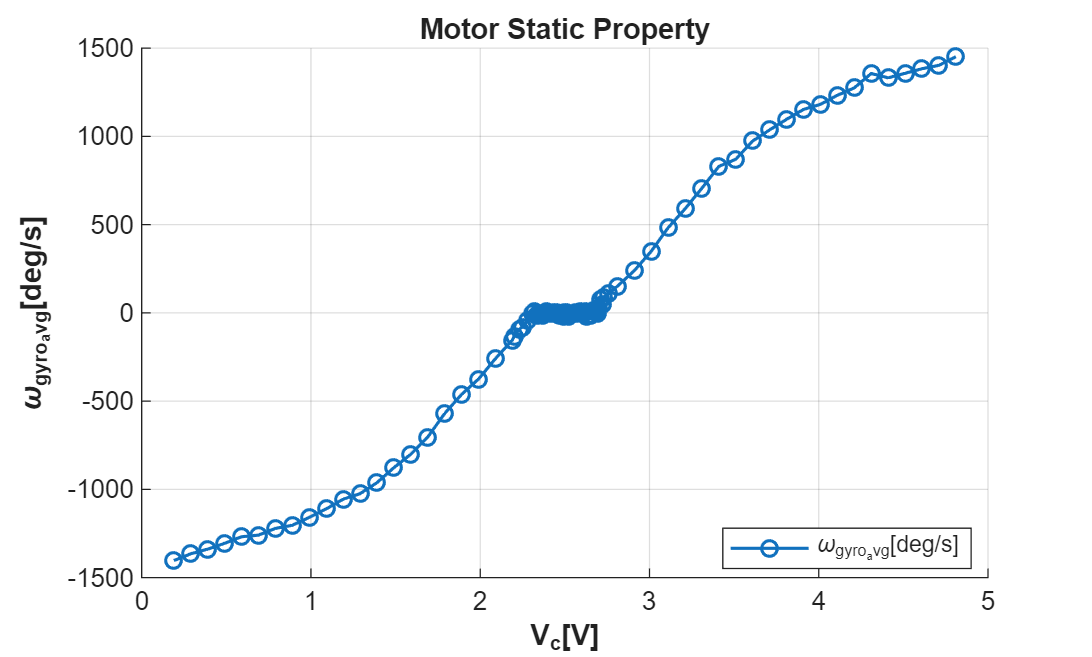

plot_sweep('../data/Static/sweep_summary.out');

Get_fitting_Quadratic('../data/Static/sweep_summary.out');

Positive region: W = -303.8233*V^2 + 2948.9925*V + -5733.2060
Negative region: W = 340.3554*V^2 + -231.7387*V + -1273.1276


## 2. Obtain Static Motor Property

### 1) Dead-zone at 2.3[V] -> 2.7[V] voltage

### 2) Saturation of Wgyro to 25 [rad/ses] (219 rpm)  (3.66 Hz)

### 3) Linear region positive from 2.7[V] to 3.5[V], negative from 2.3[V] to 1.5[V]

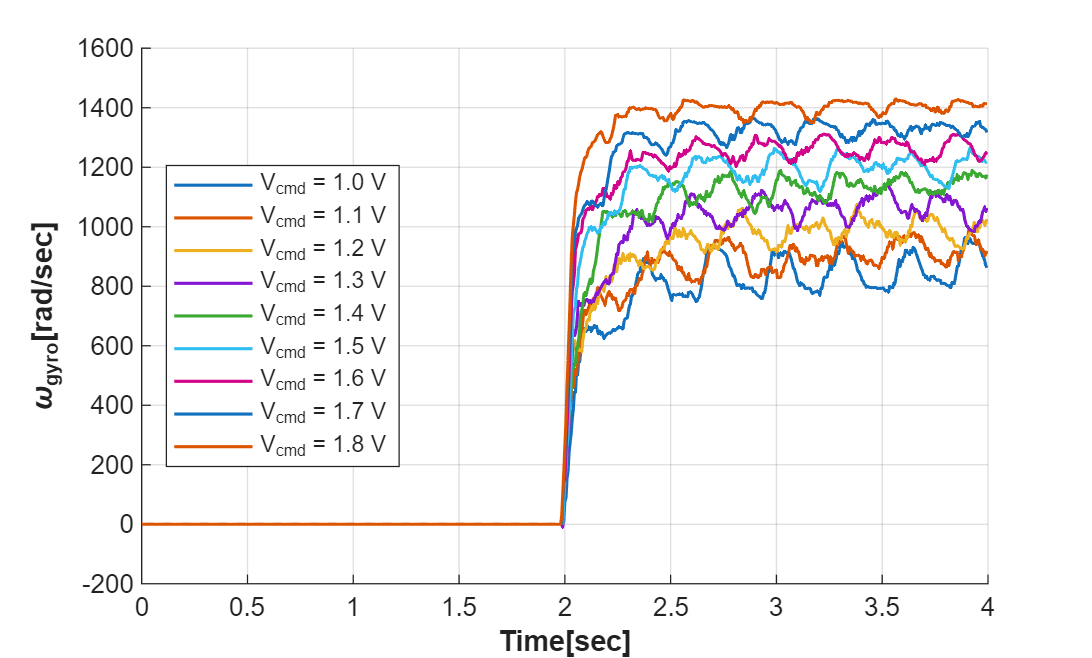

plot_Wgyro('Slewrate');


find_coff(0.05, 0.2302, 1.842, 2.72, 2.85, 4.80);

a = 0.272548
b = 0.645053
c = 2.687066


find_coff(-0.05,-0.2436,-1.7824,2.28,2.15,0.3);

a = -0.306366
b = 0.581539
c = 2.309843


## 3. Validation - triangle

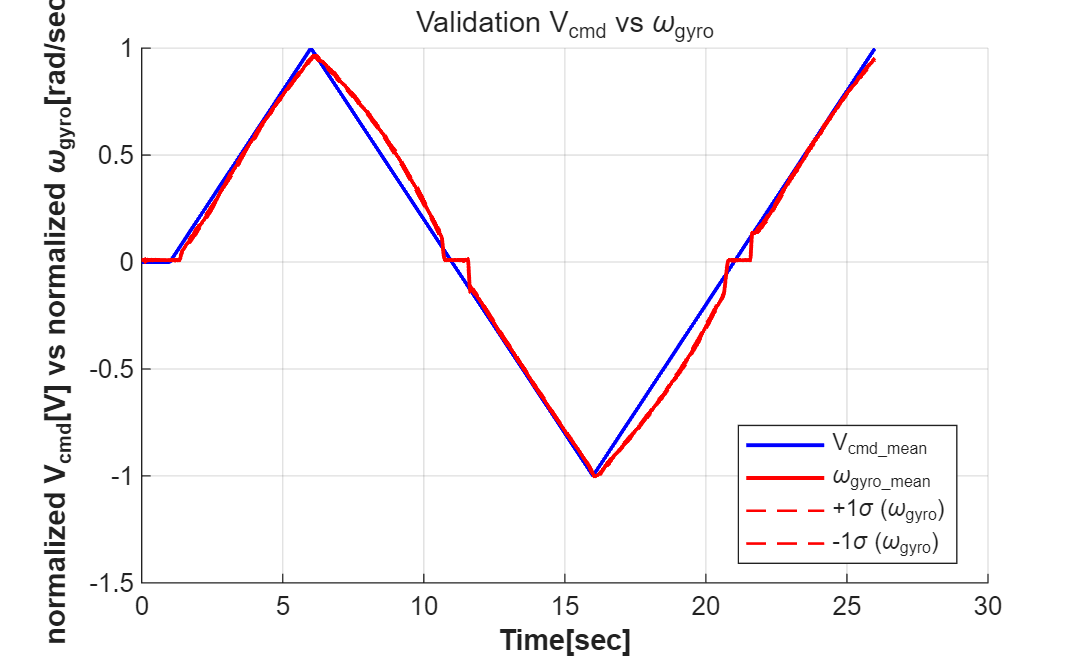

Vali_plot('tri');

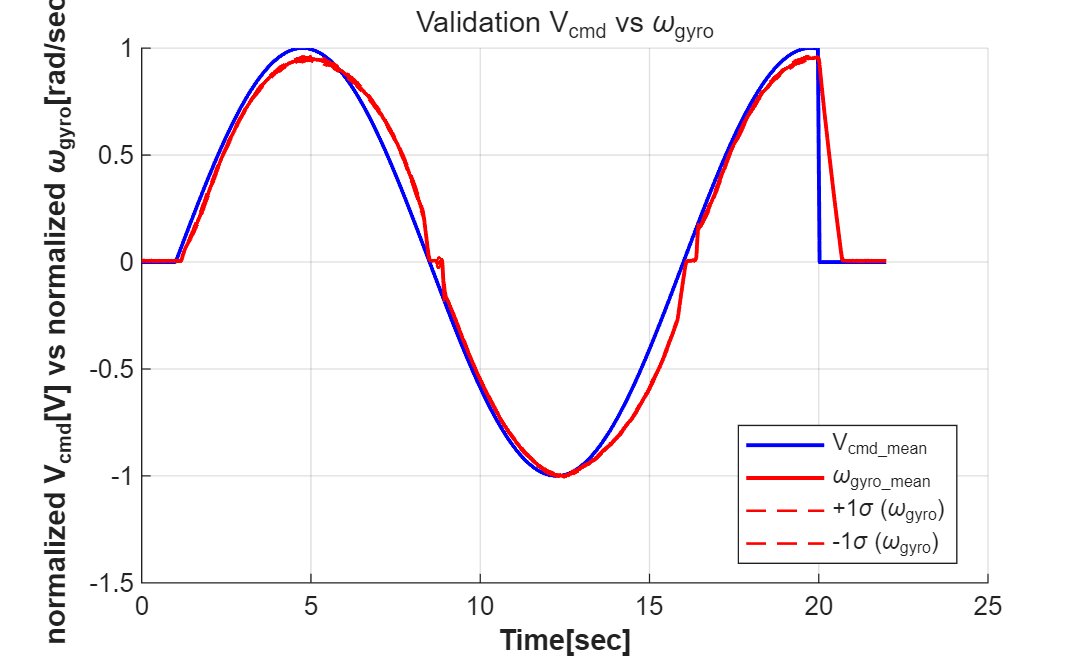

Vali_plot('sin');

## 4. Bode 

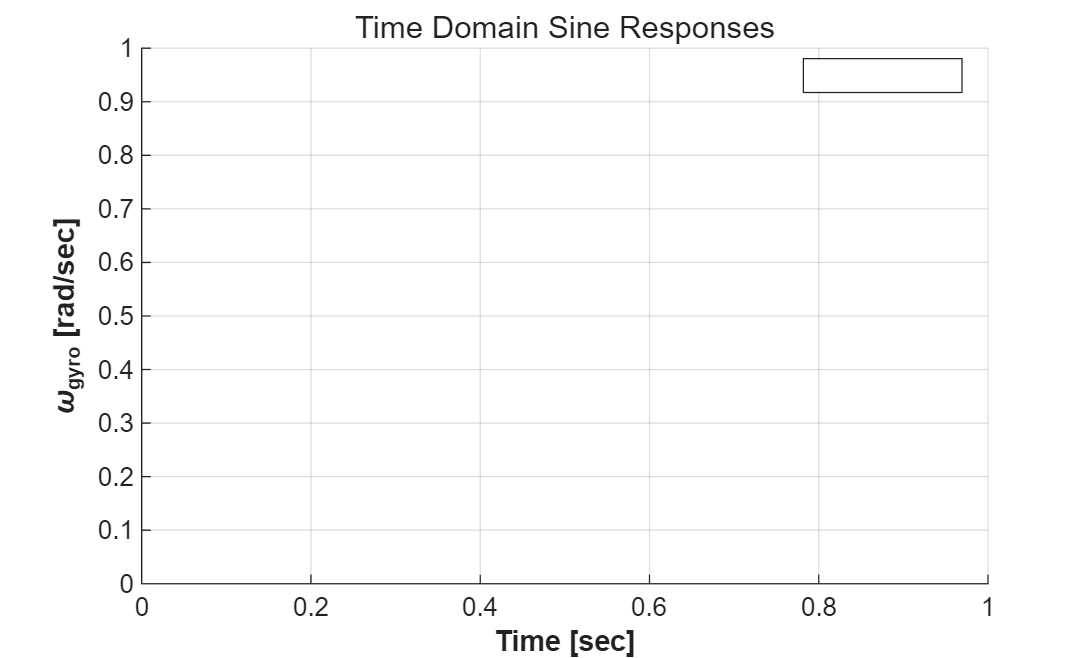

plot_BodeMag_dB('BodeMag');